% Script for live processing data from the Arduino pan-tilt 3D scanner, and
% then creating a visualization of it

% % % Initialize serial and collect data into this script (adapted from
% % % sample "matlabArduino-2021-updated-by-students.m" file

clear s
clf 
syms x 

% Choose which port to use for Arduino (hardcode based on what port it 
% mentions in the arduino IDE)
ports = 'COM9';

baudrate = 9600;
s = serialport(ports, baudrate);

% Initialize a timeout in case MATLAB can't connect to the arduino and to
% recognize when the arduino is done sending data.
timeout = 0;    

% Initialize a matrix to store the data read from the arduino
scanData = [];

% Main loop to read and store data from the Arduino
while timeout < 5       % Check if data was received
   write(s, 1, 'uint8'); % Send signal to the Arduino to begin running it's firmware
   while s.NumBytesAvailable > 0
       %
       % reset timeout
       %
       timeout = 0;
       % 
       % Store the data coming in from the arduino scan in a matrix called
       % scanData
       % 
       scanData = [scanData ; readline(s)];
   end
    pause(1);
    timeout = timeout + 1;
end

% Convert the stored data form strings into usable matrix int data 
numData = []; % Establish a matrix to contain data once it is in int form

for i = 1:height(scanData)
    % Remove the "begin" and "end" messages sent by the Arduino from the
    % data.
   if i == 1 || i == height(scanData) 
      continue 
   end
   
   % Convert the data into int form, and store in the numData matrix
   numData = [numData ; eval(scanData(i))];
end

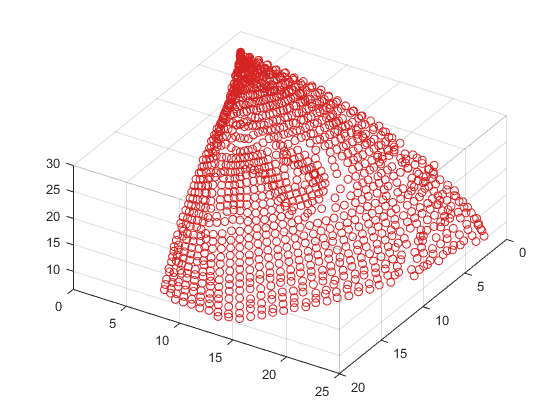


% % % Convert voltage readings from data to distance using best-fit equation
% % % from MP2FindBestFit script
% As a note, right now this data follows this structure:
% Each row is [theta, phi, voltage]

%fitFunc = 29061/1076 - (21*x)/538; % Works for measurements 5 or more inches
                                    % away, taken from MP2FindBestFit purely
                                    % for reference

% Separate the data for conversion
thetaPhi = numData(1:end, 1:2);
voltageData = numData(1:end, 3);

% Establish a matrix to stor the converted data
distanceData = [];

% Convert the sensor output voltage data into distance data
for i = 1:height(voltageData)
   x = voltageData(i);
   distanceValue = 29061/1076 - (21*x)/538;
   distanceData = [distanceData ; distanceValue];
end

% Regroup the angle and distance data
fitData = [thetaPhi distanceData];

% % % Convert data from spherical coordinates to 3D cartesian
% As a note, right now this data follows this structure:
% Each row is [theta, phi, r]

% Separate fitData into theta, phi, and r to allow for conversion
theta = fitData(1:end, 1);
phi = fitData(1:end, 2);
r = fitData(1:end, 3);

% Perform conversion from spherical coordinates to 3D cartesian.
x = r .* sind(theta) .* cosd(phi);
y = r .* sind(theta) .* sind(phi);
z = r .* cosd(theta);

% % % Create 3D visualization(s)
clf

scatter3(x, y, z); colormap('winter');

title('3D Scan of Cardboard Letter S')
xlabel('Distance (inches)')
ylabel('Distance (inches)')
zlabel('Distance (inches)')